# PID pole placement controller design - user's manual

This livescript is a brief manual in support of the ***PoleReplacement_control101.mlapp*** file which shows the results of the design of continuous and discrete PID controllers using the pole cancellation method.  Further details of these designs are described in the toolbox files below and will not be repeated here.

- ***PID_Cont_Controller_Design_with_Pole_Cancellation.mlx***

- ***discrete_models_and_discrete_PID_controller_design.mlx***

The purpose of this app is to compare the results of the designs (P, PI, PD, PIPD) so that students can get an understanding of the differing roles each compensator plays in achieving desirable behaviour. The app gives out warnings where criteria cannot be reached.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Gyula Max and Ruth Bars, Budapest University of Technology and Economics and was edited by Anthony Rossiter (University of Sheffield)

                                                                                     

## Table of Contents

- Technical background

- Use of the app

## 1. Technical background

Readers should be familiar with the files on PID controller design with pole replacement method (***PID_Cont_Controller_Design_with_Pole_Cancellation.mlx, discrete_models_and_discrete_PID_controller_design.mlx)***.

This script assumes the following block diagram (Figure 1) with system *G(s*) and compensator *M(s) or M(z)*.

or

**Figure 1**: *Block diagram structure and notation*

In the application, the PID controller replaces the poles of the two largest time constants of the process. It replaces the largest time constant with a PI controller, ensuring that the asymptotic Bode diagram of the process begins at least with a slope of -20 dB/decade, while this range is extended by replacing also the second largest time constant. Knowing the open circuit, the gain of the controller is calculated ensuring a 60° phase margin ( Pm=60° ).

The purpose of **PoleReplacement.mlapp** file is to define the continuous or the discrete PID controllers for a given plant (*G(s)*) using the pole replacement method. By this method the transfer function of the continuous or the discrete controller can be determined easily and quickly. The PID controller algorithm applies the pole cancellation method.

In continuous case the transfer function of the controller is given as:   $M_{\textrm{PID}} \left(s\right)=K_p \left(\frac{1+sT_i }{sT_i }\right)\left(\frac{1+sT_d }{1+s\frac{T_d }{n}}\right)$  where n can be chosen between 3 and 10.

In discrete case the pulse transfer function of the controller is defined as: $M_{\textrm{PID}} \left(z\right)=K_p \left(\frac{z-e^{-\frac{T_s }{T_i }} }{z-1}\right)\left(\frac{z-e^{-\frac{T_s }{T_d }} }{z}\right)$

### **1.1 Organisation of the mlapp interface: user inputs**

The mlapp file contains three blocks where the user can make their selections. The task of the main layout is to collect the input figures.

- **System description** window helps to define the **Plant** and the **Controller**. They can be defined either to write them into the main line or select them from their combo box. When one of them is written or selected the system checks it. In case of failure an error message appears in the **Message** window in the bottom left.

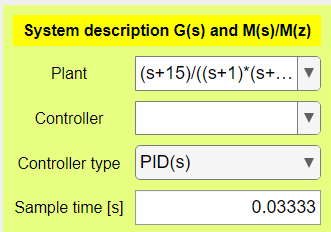

- **Control parameters**: Controllers may be selected in the **Controller** and the **Controller type **windows. In addition to the basic ( P(s), PI(s), ... ) controllers, users can also select their own controllers in the **Controller type ** window, if you have already defined them in the **Controller** window. When you want to use proportional discrete controller write i.e. 5*z/z in controller window.

- **Sample time** can also be changed here. Take into consideration Shannon's sampling theorem. The Sampling Theorem states that a signal can be exactly reproduced if it is sampled at a frequency F,  where F is greater than twice the maximum frequency in the signal. It means the sample time is smaller or equal to the half of the smallest time constant of the system observed. At least two samples are necessary from the smallest time constant ( Ts <= min(Tn)/2 ). The system checks the time constant given in this window. If your sample time is too high, it is reduced to the maximum value. In case of the former plant the smallest time constant is Ta = 1/15 = 0.0666 sec.  Using Shannon's criteria the maximal sample time is Tsmax = Ta/2 = 0.06666/2 = 0.0333 sec (Tsmax >= Ts).

- **Manually selected PID parameters. **This block allows users to change PID parameters if it is necessary. Since the forms located at the right bottom of the layout use (s + 1/T) or (z-exp(-Ts*(1/T)) ) forms, the value of 1/T can be set on the sliders. When the sliders are set to zero, the values are set to 0.1 and when a value less than 5% of the maximum value is selected, the maximum value set to half of the recent value. Finally if you set to the maximum value, the maximum value is doubled. If a PID controller is planned and you want to change its parameters, the type of the controller changes from PID(s) to User's choice and the transfer function of the controller appears in the **Controller** window. So parameters can be changed either by sliders or manually in the **Controller** window.

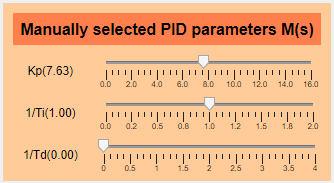

**        Results**

- Your system is defined, when the plant is accepted and the controller is also accepted or selected from the **Parameters**. To start planning push **Update System Details** button - the result can be seen in all three sheets. 

- If slides are used pushing **Update System Details** button is not necessary. Sliders invoke **Update System Details** button.

- If values of slider are changed in the Controller window  **Update System Details** button must be pushed.

### **1.2 Organisation of the mlapp interface: outputs**

- During planning, the current numerical results are shown in the lower right part of the screen. There is a special *Kp* value. If the control loop is structurally stable, the value of the loop gain is set to *Kp* = 3.1415926 (π). In this case the value of *Kp* can be set to any value (*0 < Kp < Inf*).

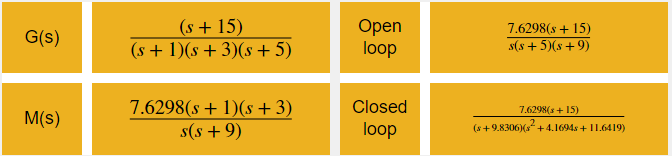   

- The system contains 3 different sheets or tabs.The default sheet is the **Update System Details** sheet. You do not have to activate it. After each calculation these sheets are updated automatically. The **System Behaviours** sheet helps you to check details of your system visually. The **Update Summary** sheet represents effects of all types of the controllers. The legend of the Step responses diagram contains the settling time, too.

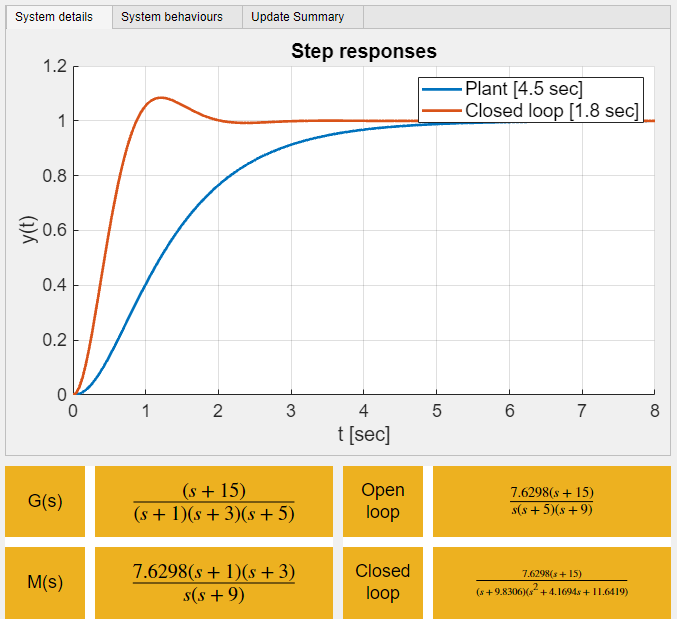

## 2. Use of the app

Open the PoleReplacement.mlapp file by selecting it from the apps in the main Matlab window and run it directly. You should see a screen shot similar to the one below. The app currently contains 3 pages and 1 activation buttons in the top left (pink coloured).

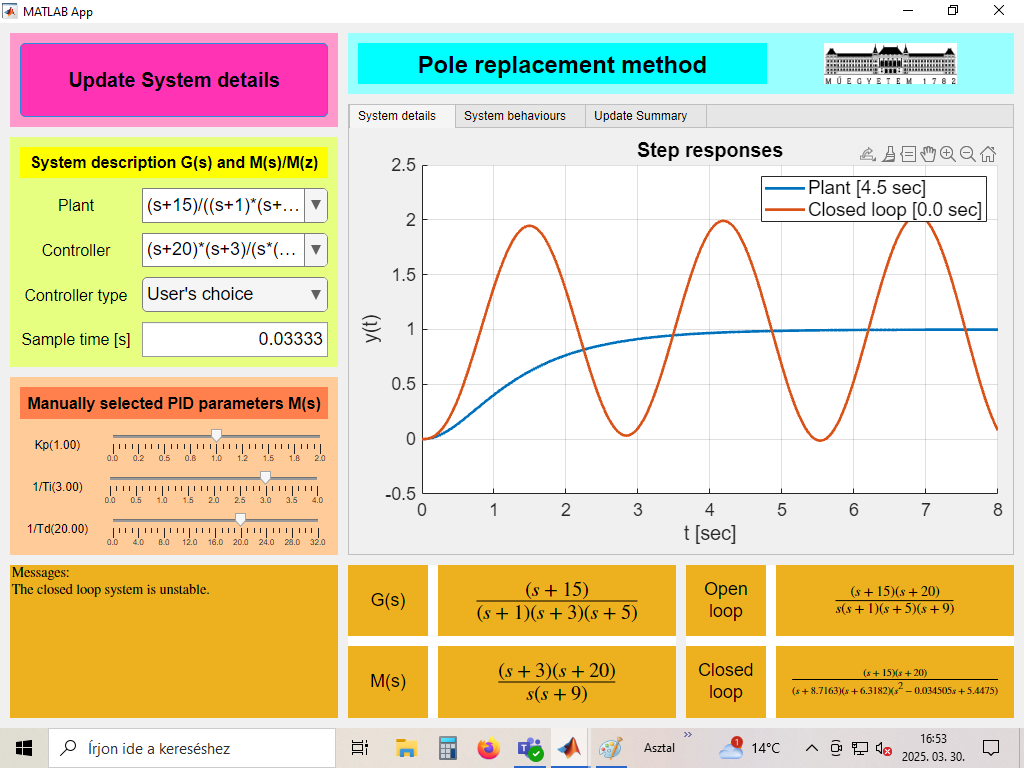

1. Users can specify the process to be controlled in the **Plant** row. The plants are always continuous. You can define the plant and the controller in several ways, i.e. with its different transfer functions as shown below 

Example:     **Plant**            2/((s+3)*(1+2*s))   or    2/(s+3)/(1+2*s) 

                    **Controller    **tf( [1 2], [1 5 4] ) 

When your plant has already defined sometimes the value of the sample time changes, sometimes not.  If a new plant is given, the maximum sample time - using Shannon's sample time theorem - is calculated.  If a new Plant is entered, the Sample time will only change if the old one is not appropriate.

If a controller has already been defined, after pressing ENTER, the **Controller type **window changes to value **User's choice**. If you specify your discrete controller, you also change the value of the **Sample time** window, if it is necessary. With a sample time greater than this sampling value, we no longer have the opportunity to sample the process correctly. The initial value of the **Sample time** (Ts) is calculated automatically. This value can be changed. The **Sample time** recommended by the program is half of the smallest time constant of the plant. If the process is delayed (Td>0), the  **Sample time** (Ts) must be chosen as Td/n, where n is a positive integer. Also check the rate of Td and the time constants (Ti). (max(Ti)/2 > Td).   If you have specified the process, the transfer function of your controller or you have selected the type of the controller to be designed, you can start the calculations by pressing the **Update System details** button. During calculation the transfer function of the designed or specified elements is displayed in the right bottom of the screen. 

2. In the **System behaviours** sheet users see the step response of the process and that of the control system with the given controller supposing unity feedback. The transfer function of the process is given at the top of the figure. The legend includes the settling time, too.

After each calculation the **System behaviours** sheet presents the recent output signals of the original plant and of the feedback control system y(t) as well as the output of the controller u(t) in the closed loop system with their settling times. The Bode and Nyquist diagrams of the open loop also can be seen. The last diagram contains two diagrams. The default diagram is the Nyquist diagram but pressing on the surface of the Nyquist diagram, the Root locus diagram appears. 

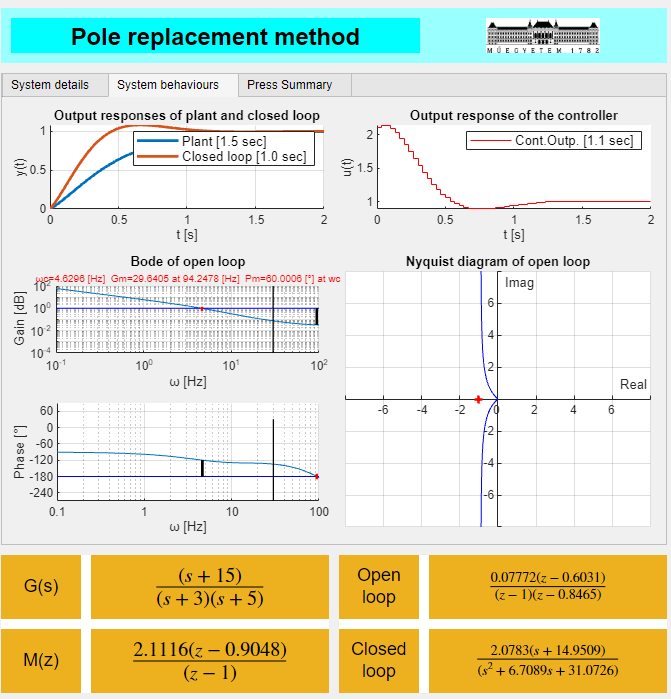

       and after clicking on surface of Nyquist diagram

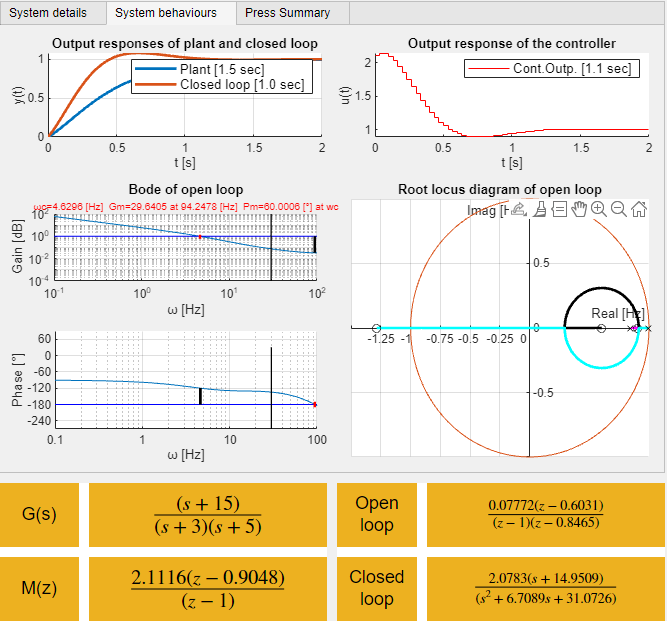

The Bode diagram of the open loop presents some important data (cut off frequency, gain and phase margins). In the case of a discrete controller, the diagram also includes the cut off frequency (2/Ts). This is necessary because the values after the sampling frequency are invalid according to Shannon's criteria. In the case of a selected controller, the gain of the controller is determined ensuring phase margin Pm=60°. Subtitle of the Bode diagram is red when some failure happens during the controller design ( i.e. Gm > 2/Ts ).

In the case of a discrete system, the root locus diagram contains the unit circle.

3. In the **Update Summary** sheet, the effect of the possible controllers with the given plant are illustrated by depicting the step responses of the closed loop system. If the control loop is structurally stable, the value of the loop gain is set to K = 3.1415926 (π). 

Other notes: 

- If you enter incorrect data, warnings are appeared in the **Message** window, but you have to correct the errors by yourself. 

- The values of the sliders are often not displayed below the sliders.

- If you design selected controllers, their parameters are not changeable. If you want to change any parameter first change one of the parameters in the **Manually selected PID parameters** window. If you change any parameter, the type of the controller changes into User's choice and now you can change the parameters in the **Controller** window.

- In the case of a new plant and/or a new controller push the Update System Details button to see the new results. 

- In case of dead time root locus diagram does not exist.

- In case of a second order oscillating plant with small damping factor evaluate critically the result of the PID design (check the Bode diagram). Pay special attention to the design of discrete controllers, because during the continuous to discrete transformation, previously non-existent zeros are created in the system. We recommend that in this case the user designs the controller independently.  